# Sistemas LTI, control por realimentación de estados estimados.

Vamos a estudiar el caso en que no tenemos acceso directo a los estados, y por tanto, dependemos de las salidas para poder controlar por realimentación de estados.

Controlable y observable:


$$$A_c =\pmatrix{1&2&0 \cr
-2&3&0\cr
1&0&-2}, \ B = \pmatrix{1& 2\cr
1&0\cr
0&0}$$



$$C_0 = \pmatrix{1& 2& 1}$$


No controlable y no observable

#### 
$$$A_i =\pmatrix{1&2&0 \cr
-2&3&0\cr
0&0&-2}, \ B = \pmatrix{1& 2\cr
1&0\cr
0&0}$$



$$C_i = \pmatrix{1 &2& 0}$$


Recuperamos nuestros sistemas de antes pero ahora, lo que hacemos es añadir la matriz $C$, ya que no podemos realimentar directamente desde los estados.

Ac = [1 2 0; -2 3 0; 1 0 -2];
B = [1 2;1 0;0 0]; %es comun a los dos sistemas
Co = [1 2 1];
Ai = [1 2 0; -2 3 0; 0 0 -2];
Ci = [1 2 0];

Calculamos la matriz de observabilidad empleando directamente el comando obsv de matlab,

Oo = obsv(Ac,Co)

Oo =      1     2     1
    -2     8    -2
   -20    20     4


Igual que para la controlabilidad, podríamos usar directamente la definición de la matriz de observabilidad,


$$\mathcal{O} = \pmatrix{C\cr  CA\cr C^2A\cr \cdots \cr CA^{n-1}}$$


cOo =[Co; Co*Ac; Co*Ac^2]

cOo =      1     2     1
    -2     8    -2
   -20    20     4


rank(Oo)

ans = 3

Oi = obsv(Ai,Ci)

Oi =      1     2     0
    -3     8     0
   -19    18     0


rank(Oi)

ans = 2

Obtenemos que el primer sistema es observable y el segundo no. En el caso del segundo, es suficiente observar la última columna de la matriz de observabilidad para darse cuenta de que no es observable.

#### Test de Autovectores.

Un par $(A,C)$ es observable si no existe ningún autovector de $A$en el kernel de $C$

Calculamos entonces los autovectores y autovalores de las matrices traspuestas de ambos sistemas

[avc,lc] = eig(Ac)

avc =    0.0000 + 0.0000i   0.3490 - 0.6045i   0.3490 + 0.6045i
   0.0000 + 0.0000i   0.6980 + 0.0000i   0.6980 + 0.0000i
   1.0000 + 0.0000i   0.0184 - 0.1591i   0.0184 + 0.1591i


lc =   -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   2.0000 + 1.7321i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 - 1.7321i


[avi,li] = eig(Ai)

avi =    0.3536 - 0.6124i   0.3536 + 0.6124i   0.0000 + 0.0000i
   0.7071 + 0.0000i   0.7071 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


li =    2.0000 + 1.7321i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   2.0000 - 1.7321i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i


De aquí podemos aprender ya muchas cosas de ambos sistemas. Para empezar podemos estudiar directamente la estabilidad de nuestros sistemas examinado los autovalores obtenidos. En ambos casos, obtenemos autovalores con parte real positiva, así que ninguno de los dos sistemas es estable.

Veamos ahora la observabilidad con el test de autovalores. Podemos multiplicar $C$ por las matrices de autovalores que hemos obtenido: 

testc = Co*avc

testc =    1.0000 + 0.0000i   1.7633 - 0.7635i   1.7633 + 0.7635i


testi = Ci*avi

testi =    1.7678 - 0.6124i   1.7678 + 0.6124i   0.0000 + 0.0000i


Observamos que en el primer caso, todos los resultados son distintos de cero, por tanto no hay ningún autovector de $A_c$ en el kernel de $C$. Sin embargo el último autovector de $A_i$ da como resultado $0$ por tanto dicho autovector está en el kernel de $B$ y el segundo sistema no es observable, como ya sabíamos. (Recordad que el test exige comprobar que no hay NINGUN autovalor de $A$ en el kernel de $C$y, por tanto, no se puede hacer del modo directo en que lo hemos hecho aquí si hay autovalores con mutiplicidad geométrica mayor que 1.)

#### Test de Lyapunov para observabilidad.

En este caso, debemos encontrar una solución $P\succ 0$ para la ecuación de Lyapunov:

 
$$A^TW+WA = -C^TC$$


Hay que recordar, que esta ecuación solo se cumple en el caso de que $A$ sea una matriz de estabilidad (Kurwith), ninguno de nuestros sistemas lo cumple, por lo que no debemos encontrar la solución deseada. Para comprobarlo, empleamos el comando de matlab lyap,

W = lyap(Ac',Co'*Co)

W =    -0.3214   -0.7857   -1.7500
   -0.7857   -0.1429    1.5000
   -1.7500    1.5000    0.2500


lW = eig(W)

lW =    -1.9405
   -0.9795
    2.7057


La matriz obtenida $W$ no es definida positiva, el sistema no es estable y por eso no obtenemos solución adecuada para la ecuación de Lyapunov. Para comprobar que sí funciona para un sistema estable, vamos a definir una nueva matriz $A_e$


$$A_e = \pmatrix{-1 &-2& -1\cr
0&-1 &-1\cr
1&-2&-2}$$


Ae = [-1 2 -1; 0 -1 -1;1 -2 -2]

Ae =     -1     2    -1
     0    -1    -1
     1    -2    -2


lAe = eig(Ae) %estable

lAe =   -3.0000 + 0.0000i
  -0.5000 + 0.8660i
  -0.5000 - 0.8660i


rank(obsv(Ae,Co)) %observable

ans = 3

Por tanto la matriz $A_e$ es una matriz de estabilidad y el par $(A_b,C_o)$ es observable. Veamos qué dice ahora el test de Lyapunov,

W = lyap(Ae',Co'*Co)

W =     0.8974    0.2308    0.3974
    0.2308    7.5385   -2.5385
    0.3974   -2.5385    1.3205


lp = eig(W)

lp =     0.1444
    1.1679
    8.4441


Todos los autovalores son positivos, lo que implica que P es definida positiva

Podemos obtener también W calculando el gramiano 'infinito'. Recordad que el gramiano 'infinito' es la única solución al test de Lyapunov de estabilidad.


$$W_0 = \int_0^\inf e^{A^T\tau}C^TCe^{A\tau}d\tau$$


definimos una funcion con el gramiano (ver final del archivo)

f=@(t)dgramo(t,Ae,Co); %handle a la funcion

Usamos el comando de matlab integral(f,t0,t1,'ArrayValued',1) el parámetro 'ArrayValued' hay que incluirlo y darle valor 1 para que sepa que el integrando tiene una matriz. De no hacerlo obtendremos un error.

W = integral(f,0,inf,'ArrayValued',1)

W =     0.8974    0.2308    0.3974
    0.2308    7.5385   -2.5385
    0.3974   -2.5385    1.3205


lW = eig(W)

lW =     0.1444
    1.1679
    8.4441


Por supuesto, obtenemos el mismo resultado que empleando la funcion lyap.

### Estabilización por realimentación de estados estimados

Volvamos a los dos sistemas del principio, el primero debería ser estabilizable, por realimentación de estados, empleando la ecuación de lyapunov. El segundo, no ya que no es posible encontrar una matriz W que cumpla con el test de Lyapunov para ninguna realimentación de estados. 

Sabemos que podemos estabilizar un sistema, empleando un parametro $\mu>0$. Para ello debemos encontrar una matriz $P\succ0$ de modo que satisfaga la ecuación de Lyapunov, 


$$P(A-BK)+(A-BK)^TP=-2\mu P$$


Para ello, empezamos por resolver la ecuación de Lyapunov


$$(-\mu I-A)W+W(-\mu I -A)^T = -BB^T$$


Vamos a elegir, por ejemplo $\mu=3$ Se debe elegir mayor que el menor autovalor  de $A_c$ en valor absoluto,  si no el sistema no será estable y no habrá solución para la ecuación de Lyapunov definida positiva (puede no haber solución en absoluto). 

Es interesante notar que en este procedimiento es el mismo que el empleado para realizar una realimentación de estados directa. Principio de separación: podemos diseñar independientemente los autovalores del sistema y los del observador.

mu = 3;
W = lyap(-mu*eye(3)-Ac,B*B')

W =     0.5357    0.1786   -0.0870
    0.1786    0.1429   -0.0504
   -0.0870   -0.0504    0.0870


lW = eig(W)

lW =     0.0556
    0.0868
    0.6232


Ahora tomamos $P = W^{-1}$ y la ganancia de nuestra realimentación será $K = \frac{1}{2}B^TP$

P = W^-1;
K = B'*P/2

K =    -0.2098    4.6341    2.4732
    3.2878   -3.7073    1.1415


Podemos comprobar donde quedan nuestros autovalores en lazo cerrado,

lAccl = eig(Ac-B*K)

lAccl =   -3.0000 + 3.0138i
  -3.0000 - 3.0138i
  -3.0000 + 0.0000i


Todos con parte entera negativa menor o igual a $-\mu$

En nuestro caso, no podemos emplear directamente los estados para realimentar y así estabilizar nuestro sistema. Debemos por tanto implementar un estimador. Para el primer sistema, esto es siempre posible, ya que nuestro sistema es observable.

Definimos un observador de la forma,

$\dot{\hat{x}} = A\hat{x} + Bu - L(\hat{y}-y)$.

Es decir, realimentamos la salida, para asegurar que es estimador y el sistema van a converger en el tiempo.

Debemos, calcular un valor adecuado de la ganancia $L$ para conseguirlo. Para hacerlo, es suficiente obtener una ganacia que estabilice el par $(A^T,C^T)$

y podemos emplear las mismas técnicas que hemos empleado en el caso de sistemas controlables,

#### Obtención de L mediante el método de Lyapunov.

Aplicamos el método de Lyapunov para estabilizar el par $A^T,C^T)$

Sabemos que podemos estabilizar el sistema, empleando un parametro $\mu>0$. Para ello debemos encontrar una matriz $P\succ0$ de modo que satisfaga la ecuación de Lyapunov, 


$$P(A^T-C^TK)+(A^T-C^TK)^TP=-2\mu P$$


Para ello, empezamos por resolver la ecuación de Lyapunov


$$(-\mu I-A^T)W+W(-\mu I -A) = -C^TC$$


Vamos a elegir, por ejemplo $\mu=5$. Se debe elegir de modo que la parte real de los autovalores del estimador, sea menor que los correspondientes al sistema realimentado, de este modo el estimador converge al sistema más rápido de lo que éste último converge a 0.

mu = 5;
W = lyap(-mu*eye(3)-Ac',Co'*Co)

W =     0.1108    0.1462    0.1278
    0.1462    0.2134    0.1586
    0.1278    0.1586    0.1667


lW = eig(W)

lW =     0.0023
    0.0298
    0.4587


Ahora tomamos $P = W^{-1}$ y la ganancia de nuestra realimentación será $K = \frac{1}{2}CP$. Por último recordar que para nuestro observador debemos tomar $L = K^T$

L = (Co*W^-1)'/2 

L =   -29.1667
   19.8333
    6.5000


Podemos comprobar que la matriz $A-LC$ es una matriz de estabilidad,

eig(Ac-L*Co)

ans =   -5.0000 + 9.6954i
  -5.0000 - 9.6954i
  -5.0000 + 0.0000i


Y comprobar qué tal estima nuestro estimador..

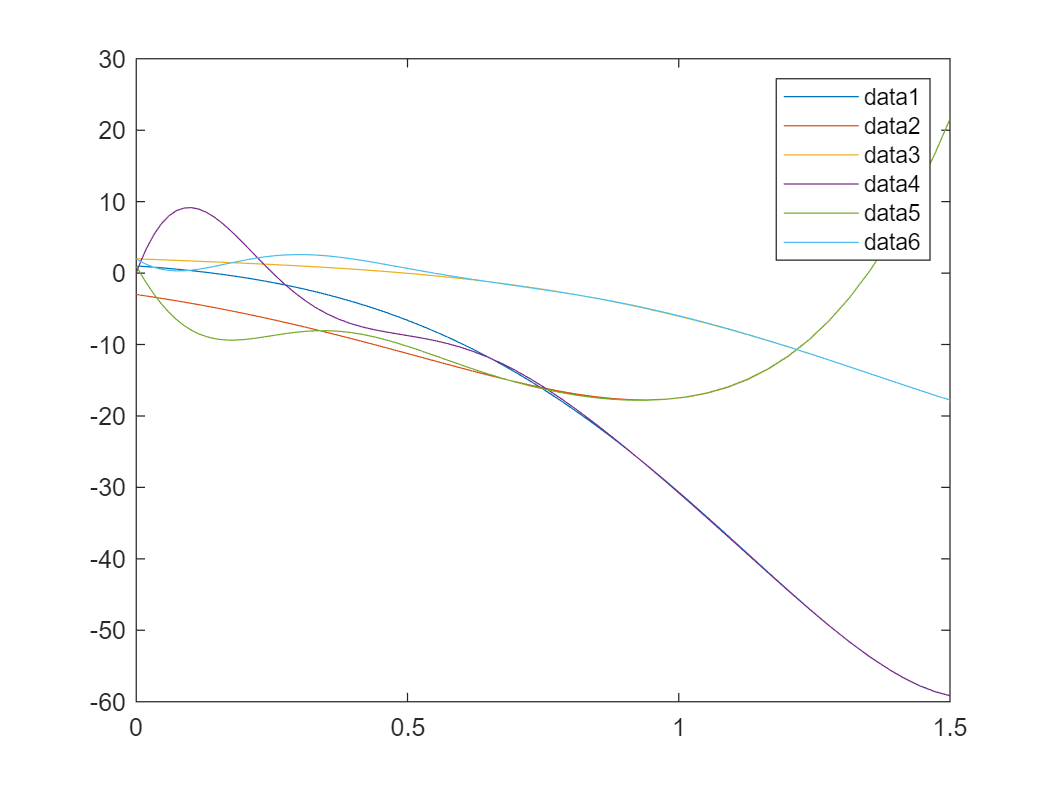

sys = @(t,xt)estimador_lineal(t,xt,Ac,Co,L);
tf = 1.5;
x0 = [1;-3;2;0;1;2];%Las tres primeras condiciones corresponden al estado.
% Las tres siguientes al estimador
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(1)
plot(t,x)
legend

Ahora tenemos todos los ingredientes para diseñar nuestro control por realimentación de estados estimados.

Para ello, construimos el sistema ampliado,


$$\pmatrix{\dot{x} \cr \dot{\hat{x}}} = \pmatrix{A & -BK\cr LC & A-BK - LC }\pmatrix{x \cr \hat{x}}$$


Sin embargo, para darle un cierto realismo al asunto, Deberíamos separa las entradas, aunque sean realimentadas, de los estados.


$$\pmatrix{\dot{x} \cr \dot{\hat{x}}} = \pmatrix{A & 0\cr 0 & A-BK-LC }\pmatrix{x \cr \hat{x}}+\pmatrix{B\cr  0}u +\pmatrix{0\cr L}y\\
u = \pmatrix{-K\hat{x}} \\
y = Cx\\
\hat{y} = C\hat{x}$$


No es desde luego la única forma de representarlo. Pero en ésta se subraya que la única entrada al sistema es $u$ y la única entrada al estimador es $y$

Vamos pues a simular nuestro sistema. Para ello creamos una función para

pasarsela a ode45 como en los ejemplos anteriores. Para facilitar el cálculo al integrador, es buena idea construir una sola matriz ampliada con todas las realimentaciones

Amp = [Ac -B*K; L*Co  Ac-B*K-L*Co] 

Amp =     1.0000    2.0000         0   -6.3659    2.7805   -4.7561
   -2.0000    3.0000         0    0.2098   -4.6341   -2.4732
    1.0000         0   -2.0000         0         0         0
  -29.1667  -58.3333  -29.1667   23.8008   63.1138   24.4106
   19.8333   39.6667   19.8333  -21.6236  -41.3008  -22.3065
    6.5000   13.0000    6.5000   -5.5000  -13.0000   -8.5000




sys = @(t,x)sistema_lineal_obs(t,x,Amp);
tf = 2;
x0 = [1;-3;2;0;1;2];%Las tres primeras condiciones corresponden al estado.
% Las tres siguientes al estimador
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(2)

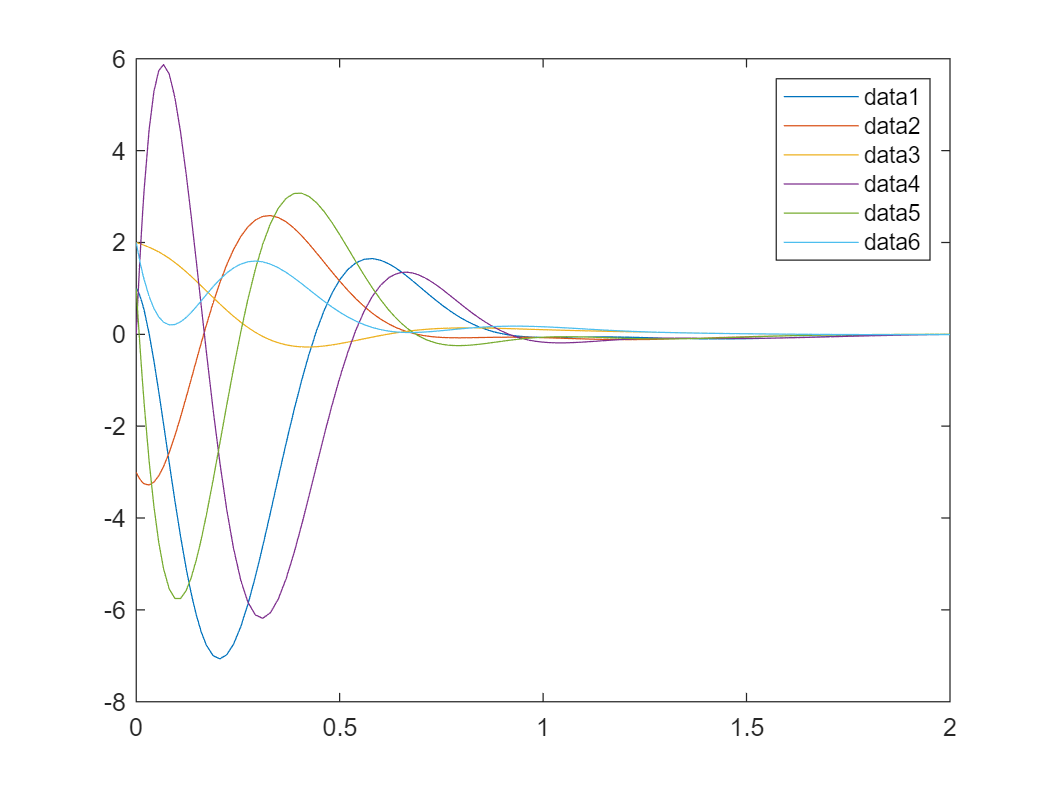

plot(t,x)
legend

Además de colocar los autovalores empleando el método de Lyapunov,

podemos colocarlos empleando place. Esto nos da libertad para poner los autovalores del controlador y del estimador donde queramos.

Primero colocamos los del controlador, nuestro sistema tiene dimensión $n=3$luego debemos colocar tres autovalores, por ejemplo $\lambda = [-3, -4,-4]$ 

lambda = [-3 -4 -5];
K = place(Ac,B,lambda)

K =    -2.0000    8.0000         0
    4.0000   -3.0000    1.0000


eig(Ac-B*K)

ans =    -3.0000
   -4.0000
   -5.0000


Ahora ponemos los del estimador, procuramos ponerlos a la izquierda de los del controlador, para que estimador converja antes. $\lambda = [-4,-5,-6]$

K2 = place(Ac',Co',lambda)

K2 =    -2.1667    8.6667   -1.1667


L = K2'

L =    -2.1667
    8.6667
   -1.1667


eig(Ac-L*Co)

ans =    -5.0000
   -4.0000
   -3.0000


Podemos, igual que antes, ver como se comporta nuestro estimador

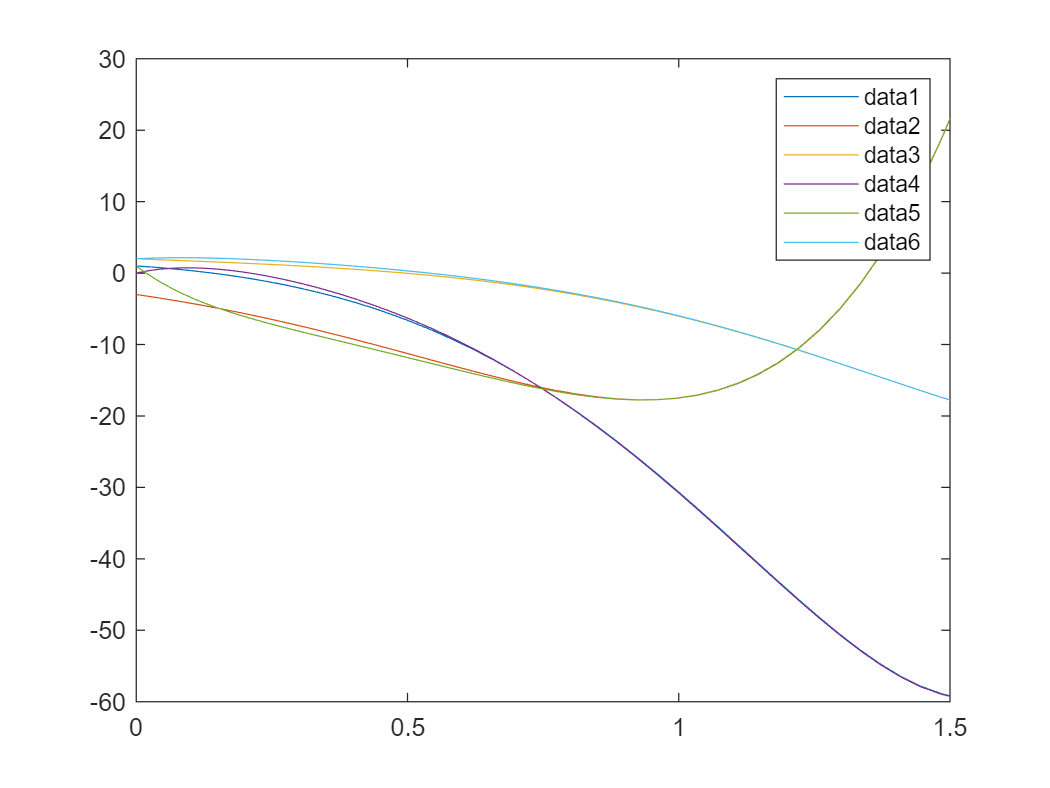

sys = @(t,xt)estimador_lineal(t,xt,Ac,Co,L);
tf = 1.5;
x0 = [1;-3;2;0;1;2];%Las tres primeras condiciones corresponden al estado.
% Las tres siguientes al estimador
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(3)
plot(t,x)
legend

Los autovalores tienen parte real más negativa, así que todo es más rápido.

Por último podemos emplear la realimentación con los estados estimados para estabilizar nuestro sistema,

Amp = [Ac -B*K; L*Co  Ac-B*K-L*Co] 

Amp =     1.0000    2.0000         0   -6.0000   -2.0000   -2.0000
   -2.0000    3.0000         0    2.0000   -8.0000         0
    1.0000         0   -2.0000         0         0         0
   -2.1667   -4.3333   -2.1667   -2.8333    4.3333    0.1667
    8.6667   17.3333    8.6667   -8.6667  -22.3333   -8.6667
   -1.1667   -2.3333   -1.1667    2.1667    2.3333   -0.8333


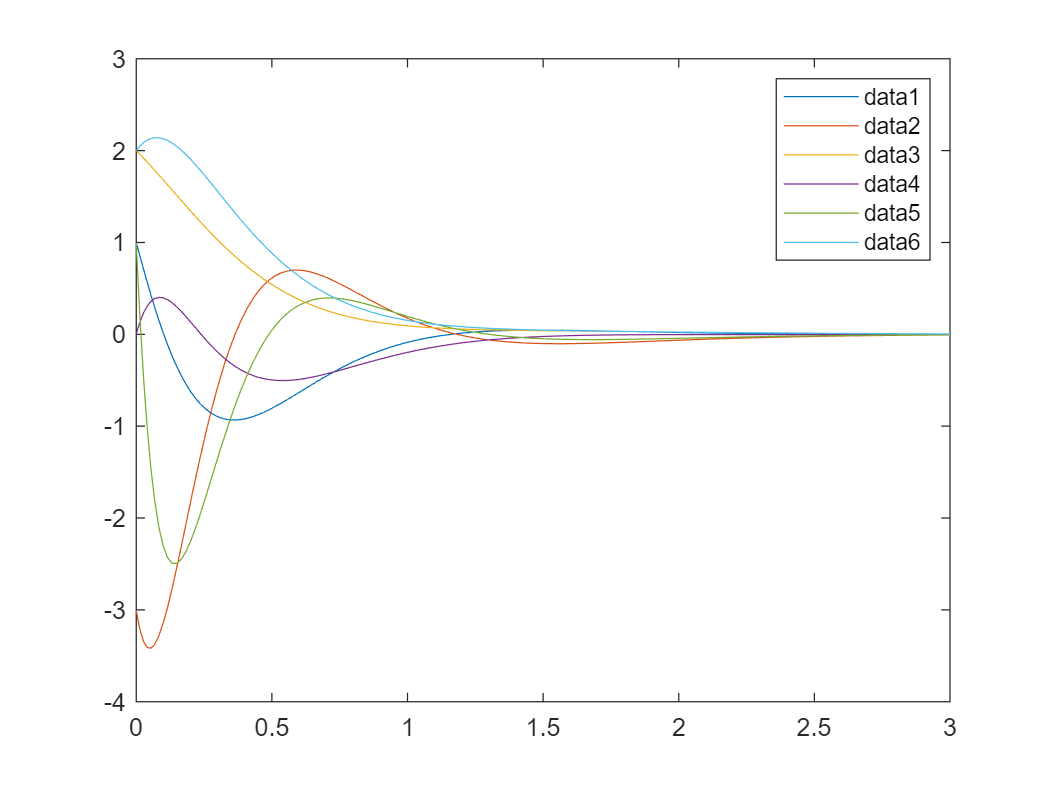


sys = @(t,x)sistema_lineal_obs(t,x,Amp);
tf = 3;
x0 = [1;-3;2;0;1;2];%Las tres primeras condiciones corresponden al estado.
% Las tres siguientes al estimador
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(4)
plot(t,x)
legend

function  dwr= dgramo(t,A,C)
%esta función permite construir el valor del integrando del grammiano de
%obsevabilidad para un par A,C y un tiempo final t1,tiempo inicial t0=0
%si creamos un handle f = @(t)gramr(t,t1,A,C) in lo pasamos a la funcion de
%matlab integral, obtenemos el valor de gramiano Wo(t1,0)
dwr = expm(A'*t)*(C'*C)*expm(A*t);
end

function xtdot = estimador_lineal(t,xt,A,C,L)
%Separo los estados de la planta de los del estimador. Deben estar
%juntos para que me los coja ode45
x = xt(1:length(xt)/2); %estados del sistema
xhat = xt(length(xt)/2+1:end);
xdot = A*x; %no le doy entrada lo dejo que evolucione
xhatdot = A*xhat - L*C*(xhat -x);
xtdot=[xdot;xhatdot];
end

function xdot = sistema_lineal_obs(t,x,A)
%El estado x debe incluir tanto los estados como los observadores.
%Solo se usa una matriz A que debe ser la ampliada con todas las
%realimentaciones incluidas
% primero los estados y despues los estimadores 
 xdot = A*x;
end